#### 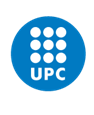

#### ADVANCED AEROELASTICITY

#### Mid-term Exam

*(Ricard Arbat Carandell)*

The figure below represents a simple model of an aircraft on its reference (undeformed) configuration, with the front panel (1) representing the main wing, and the rear panel (2) representing the tail. Both panels and the middle shaft have uniformly distributed masses given by $\sigma$ and $\lambda
$, respectively (see figure).  

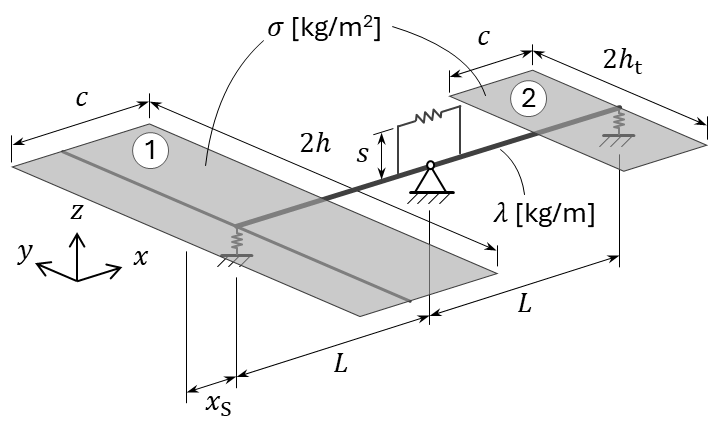

The figure below shows a generic deformed configuration of the system under an airstream at a given velocity $U_\infty$. Note: the tail panel (2) is rigidly attached to the middle shaft, so it cannot rotate (twist) with respect to it. The panels cannot rotate around the x-axis.

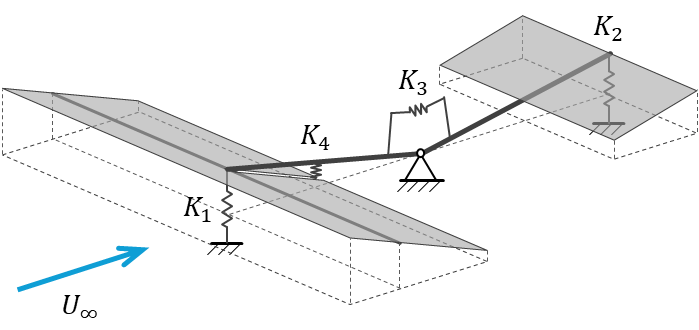

Under the hypothesis:

- All angles and displacements are small.

- The panels are flat and thin.

- $L\gg c$, so the aerodynamic influence between the front and rear panels can be neglected. Note: this means that the lift forces in each panel depend only on their own angles of attack.

- Mass apparent terms in the aerodynamic loads, i.e., those depending on second-order time derivatives of the degrees of freedom, can be neglected.

- Consider air's density $\rho= $ 1.225 kg/m${}^3$.

The following is asked:

**a) [0.5 pt] **Identify an admissible set of degrees of freedom and define the corresponding system kinematics.

**b)** **[2.5 pt]** Obtain the corresponding mass and stiffness matrices.

**c)** **[0.5 pt]** Obtain the structural modes and natural frequencies.

**d) [2.5 pt]** Obtain the external loads matrices resulting from imposing the aeroelastic coupling in the general dynamic context.

**e) [1 pt]** Obtain the divergence speed under static conditions.

**f) [1.5 pt] **Obtain the flutter speed choosing: p-method **[+ 0 pt]**, k-method **[+ 1.0 pt]**, pk-method **[+ 1.5 pt]**, or all three **[+ 2.5]**. Note: for k and pk methods, consider Theodorsen's model for unsteady aerodynamics. 

**------------ IMPORTANT ------------**

To get the problem's data, ***click*** the button below (all units are in SI):

 
% Generate data
run("data_generator.p");

% Create data.mat file
%save("data.mat","c","h","ht","xs","L","s","sigma","lambda","K1","K2","K3","K4")

A **data.mat** file containing the problem's data will be generated (to produce a new set of data first delete the data.mat file or move it to a different directory). When submitting your solution to Atenea, make sure to upload this data file. You can answer the problem's questions in this same live script Matlab file, combining fragments of text with code. 

**-------------------------------------------**

**SOLUTION**

*(Write your solution code/text here)*

Every time I execute the code a data.m mat is created. Here I load it in order to have the variables available.

% Load data
load("data.mat","c","h","ht","xs","L","s","sigma","lambda","K1","K2","K3","K4");



% Save variables in numeric
cnum = c;
hnum = h;
htnum = ht;
xsnum = xs;
Lnum = L;
snum = s;
sigmanum = sigma;
lambdanum = lambda;
K1num = K1;
K2num = K2;
K3num = K3; 
K4num = K4;
Uinfnum = 1;
rhoinfnum = 1.225;


**a) Identify an admissible set of degrees of freedom and define the corresponding system kinematics.**

***System diagram***

We can define 3 DOFs for the system. In this case, the angular movmenets of the bars (gamma) and the angular movement of the first panel (theta). All the coordinates go from left to right. (x1 is the start of the panel 1, not the spring position)

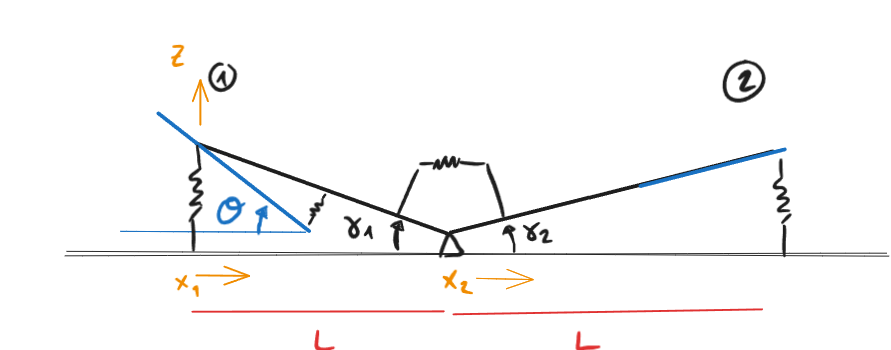

***Variables***

Therefore, the variables can now be defined.

% Symbolic variables
syms x y z t 
syms theta(t) gamma1(t) gamma2(t) delta_theta(t) delta_gamma1(t) delta_gamma2(t)

q = {theta(t) gamma1(t) gamma2(t)};
qd = {delta_theta(t) delta_gamma1(t) delta_gamma2(t)};

% Symbolic parameters
xs = sym("x_s");
h = sym("h");
ht = sym("h_t");
c = sym("c");
s = sym("s");
sigma = sym("sigma");
lambda = sym("lambda");
K1 = sym("K1");
K2 = sym("K2");
K3 = sym("K3");
K4 = sym("K4");
L = sym("L");
Uinf = sym("U_inf");
rhoinf = sym("rho_inf");
Ck = sym("Ck");

***Kinematics***

Now one can define the kinematics of the system. W defines the vertical movement of the point depending on the variables. In this case, no movement depends on the y, only the x.

% Kinematics
w1(x,t) = gamma1*L - theta*(x-xs) % panel1 (goes from start of panel 1 to end at c. At xs only gamma1 movement)

$$w1(x, t) = L\,\gamma_{1}\left(t\right)-\theta \left(t\right)\,\left(x-x_{s}\right)$$

w2(x,t) = gamma2*(L-c+x) % panel 2 (goes from start of panel 2 to end at c)

$$w2(x, t) = \gamma_{2}\left(t\right)\,\left(L-c+x\right)$$

wb1(x,t) = gamma1*(L-x) % bar panel 1 (from bar start to end at L)

$$wb1(x, t) = \gamma_{1}\left(t\right)\,\left(L-x\right)$$

wb2(x,t) = gamma2*x % bar panel 2 (from bar start to end at L)

$$wb2(x, t) = x\,\gamma_{2}\left(t\right)$$

**b) Obtain the corresponding mass and stiffness matrices.**

***Energies***

For the kinetic, we take in account both the masses of the panels and the bars

% Kinetic energy
disp("The kinetic energy equation yields:")

The kinetic energy equation yields:


T = int(int(sigma/2*(diff(w1,t))^2,x,0,c),y,0,2*h) + ... % panel 1 (int panel start to c, and for the with 2h)
int(int(sigma/2*(diff(w2,t))^2,x,0,c),y,0,2*ht) + ... % panel 2 (int panel start L - c to L, and for the with 2ht)
int(lambda/2*(diff(wb1,t))^2,x,0,L) + ... % bar panel 1 (int from bar start to L)
int(lambda/2*(diff(wb2,t))^2,x,0,L) % bar panel 2 (int from bar start to L)

$$T(t) = \begin{array}{l} \frac{L^{3}\,\lambda \,{\left(\frac{\partial }{\partial t}\gamma_{1}\left(t\right)\right)}^{2}}{6}+\frac{L^{3}\,\lambda \,\sigma_{2}}{6}+\frac{c^{3}\,h\,\sigma \,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{3}+c\,h\,\sigma \,{\sigma_{1}}^{2}-c^{2}\,h\,\sigma \,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{c\,h_{t}\,\sigma \,\sigma_{2}\,\left(3\,L^{2}-3\,L\,c+c^{2}\right)}{3}\\ \mathrm{where}\\ \sigma_{1}=L\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)+x_{s}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\gamma_{2}\left(t\right)\right)}^{2} \end{array}$$

And for the potential, we consider the energies of the springs

% Potential energy
disp("The potential energy equation yields:")

The potential energy equation yields:


U = K1/2*(w1(xs,t))^2 + ... % spring 1 from panel (position xs with respect to panel start )
    K2/2*(w2(c,t))^2 + ... % spring 2 at end of panel 2 (position c with respect to panel start.)
    K3/2*(gamma1(t)*s + gamma2(t)*s)^2 + ... % as both gammas increase or decrease, the potential increases
    K4/2*(wb1(c-xs,t) - w1(c,t))^2 % spring between bar 1 and panel 1 (position c of bar 1, and end c of panel 1)

$$U = \frac{K_{3}\,{\left(s\,\gamma_{1}\left(t\right)+s\,\gamma_{2}\left(t\right)\right)}^{2}}{2}+\frac{K_{4}\,{\left(\gamma_{1}\left(t\right)\,\left(L-c+x_{s}\right)-L\,\gamma_{1}\left(t\right)+\theta \left(t\right)\,\left(c-x_{s}\right)\right)}^{2}}{2}+\frac{K_{1}\,L^{2}\,{\gamma_{1}\left(t\right)}^{2}}{2}+\frac{K_{2}\,L^{2}\,{\gamma_{2}\left(t\right)}^{2}}{2}$$

***Mass and stiffness matrices***

Now we can calculate the matrices

% Mass matrix
for i=1:3
    for j=1:3
        M(i,j) = simplify(diff(diff(diff(T,diff(q{i},t)),t),diff(diff(q{j},t),t)));
    end
end
disp("The mass matrix is:")

The mass matrix is:


M

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{2\,c\,h\,\sigma \,\left(c^{2}-3\,c\,x_{s}+3\,{x_{s}}^{2}\right)}{3} & \sigma_{1} & 0\\ \sigma_{1} & \frac{\lambda \,L^{3}}{3}+2\,c\,h\,\sigma \,L^{2} & 0\\ 0 & 0 & \frac{L^{3}\,\lambda }{3}+\frac{2\,c\,h_{t}\,\sigma \,\left(3\,L^{2}-3\,L\,c+c^{2}\right)}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L\,c\,h\,\sigma \,\left(c-2\,x_{s}\right) \end{array}$$


% Stiffness matrix
for i=1:3
    for j=1:3
        K(i,j) = simplify(diff(diff(U, q{i}), q{j}));
    end
end
disp("And the stiffness matrix is:")

And the stiffness matrix is:


K

$$K = \left(\begin{array}{ccc} K_{4}\,{\left(c-x_{s}\right)}^{2} & -K_{4}\,{\left(c-x_{s}\right)}^{2} & 0\\ -K_{4}\,{\left(c-x_{s}\right)}^{2} & K_{1}\,L^{2}+K_{3}\,s^{2}+K_{4}\,{\left(c-x_{s}\right)}^{2} & K_{3}\,s^{2}\\ 0 & K_{3}\,s^{2} & K_{2}\,L^{2}+K_{3}\,s^{2} \end{array}\right)$$


% And the numerical matrices are obtained
Mnum = double(subs(M,[xs,h,ht,c,sigma,lambda,L],[xsnum,hnum,htnum,cnum,sigmanum,lambdanum,Lnum]));
Knum = double(subs(K,[xs,h,ht,c,s,L,K1,K2,K3,K4],[xsnum,hnum,htnum,cnum,snum,Lnum,K1num,K2num,K3num,K4num]));

**c) Obtain the structural modes and natural frequencies.**

***Modes and natural frequencies***

The modes of vibration and natural frequencies can also be obtained by solving the eigenproblem with the stiffness and mass matrices

% Eigenvalues and eigenvectors calculation
[Q,W] = eig(Knum,Mnum);

% Natural frequencies
wn = sqrt(diag(W))/2/pi

wn =     1.3458
    2.3083
    2.3131



disp(["The natural frequencies are: ",num2str(wn(1)),",",num2str(wn(2)),",",num2str(wn(3))," Hz"])

    "The natural frequ…"    "1.3458"    ","    "2.3083"    ","    "2.3131"    " Hz"



disp(["The first mode: theta:",num2str(Q(1,1)),",gamma1:",num2str(Q(1,2)),",gamma2:",num2str(Q(1,3))," Hz"])

    "The first mode: t…"    "-0.33222"    ",gamma1:"    "1.6632"    ",gamma2:"    "-0.2205"    " Hz"



disp(["The second mode:  theta:",num2str(Q(2,1)),",gamma1:",num2str(Q(2,2)),",gamma2:",num2str(Q(2,3))," Hz"])

    "The second mode: …"    "0.061119"    ",gamma1:"    "0.042885"    ",gamma2:"    "-0.0057656"    " Hz"



disp(["The third mode:  theta:",num2str(Q(3,1)),",gamma1:",num2str(Q(3,2)),",gamma2:",num2str(Q(3,3))," Hz"])

    "The third mode:  …"    "-0.00014459"    ",gamma1:"    "-0.016723"    ",gamma2:"    "-0.12592"    " Hz"



**d) Obtain the external loads matrices resulting from imposing the aeroelastic coupling in the general dynamic context.**

***Lifts***

The lifts per unit of span can be defined as following.

% Coefficients
Cla = 2*pi;
xp = c/4;

% Lifts
l1 = 0.5*rhoinf*Uinf^2*c*Cla*theta;
l2 = -0.5*rhoinf*Uinf^2*c*Cla*gamma2;

***Virtual works***

And the virtual works are obtained with the delta variables. As there's no flap, there's no f_delta vector.

% Delta kinematics
delta_w1(x,t) = delta_gamma1*L - delta_theta*(x-xs); % panel1 (goes from start of panel 1 to end at c. At xs only gamma1 movement)
delta_w2(x,t) = delta_gamma2*(L-c+x); % panel 2 (goes from start of panel 2 to end at c)


% Virtual works
dW = int(l1*delta_w1(xp,t),y,0,2*h) + ... % lift applied to xp (starting from the front of the airfoil 1)
    int(l2*delta_w2(xp,t),y,0,2*ht); % lift applied to xp (starting from the front of the airfoil 2)

% A matrix
for i=1:3
    for j=1:3
        A(i,j) = simplify(diff(diff(dW, qd{i}), q{j}));
    end
end

Anum = double(subs(A,[Uinf,rhoinf,xs,h,ht,c,sigma,lambda,L],[Uinfnum,rhoinfnum,xsnum,hnum,htnum,cnum,sigmanum,lambdanum,Lnum]));



The aeroelastic coupling matrix with the simple model is (including h and ht):


$$A0 = \left(\begin{array}{ccc} -2\,h\,\left(\frac{c}{4}-x_{s}\right) & 0 & 0\\ 2\,L\,h & 0 & 0\\ 0 & 0 & -2\,h_{t}\,\left(L-\frac{3\,c}{4}\right) \end{array}\right)$$

And the aeroelastic coupling matrix whitout the h and ht gives us:


$$A0 = \left(\begin{array}{ccc} 2\,x_{s}-\frac{c}{2} & 0 & 0\\ 2\,L & 0 & 0\\ 0 & 0 & \frac{3\,c}{2}-2\,L \end{array}\right)$$

**e) Obtain the divergence speed under static conditions.**

***Divergence speed***

The divergence speed can be found by solving the eigenproblem with the stiffness matrix and the aeroelastic coupling matrix.

% Eigenproblem
[v,d] = eig(Knum,Anum);

% Velocities at the diagonal of the eigenvalues
Ud = sqrt(diag(d));

% Classifying the velocities
for i = 1:size(d,1)
    if Ud(i) < 0                % No negative values
        Ud(i) = 0;
    elseif isreal(Ud(i)) == 0   % No complex values
        Ud(i) = 0;
    elseif Ud(i) > 10^10        % No infinite values
        Ud(i) = 0;
    end
end

% Getting the minimum positive divergence speed different from 0
if min(Ud(Ud>0)) ~= 0
    Ud = min(Ud(Ud>0));
else
    Ud = 0;
end
Ud

Ud = 10.5109


disp(["The divergence speed is: ",num2str(Ud),"m/s"])

    "The divergence speed is: "    "10.5109"    "m/s"



**f) Obtain the flutter speed for p-method, k-method and pk-method. ****Note****: for k and pk methods, consider Theodorsen's model for unsteady aerodynamics. **

***Theodorsen's aerodynamic model***

Firstly, we will define the lifts and moments considering the Theodorsen's model, to which we will apply the virtual works.

% Some variables
b = xs - 3/4*c;
a = xs - 1/4*c;

% Equivalent vertical movements
eta1 = w1(xp,t); % vertical movement at xp (1/4*c)
eta2 = w2(xp,t); % vertical movement at xp (1/4*c)

% Transient lifts and moments
l1t = pi*rhoinf*Uinf^2*c*Ck*(theta - diff(theta,t)*b/(2*c) - diff(eta1,t)/(2*c)) + pi*rhoinf*Uinf^2*c*diff(theta,t)

$$l1t(t) = \pi \,{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\frac{\partial }{\partial t}\theta \left(t\right)+\mathrm{Ck}\,{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\pi \,\left(\theta \left(t\right)+\frac{\left(\frac{c}{4}-x_{s}\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-L\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{c\,2}+\frac{\left(\frac{3\,c}{4}-x_{s}\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2\,c}\right)$$

l2t = -pi*rhoinf*Uinf^2*c*Ck*(gamma2 - diff(gamma2,t)*b/(2*c) - diff(eta2,t)/(2*c)) - pi*rhoinf*Uinf^2*c*diff(gamma2,t)

$$l2t(t) = -{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\pi \,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)-\mathrm{Ck}\,{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\pi \,\left(\gamma_{2}\left(t\right)-\frac{\left(L-\frac{3\,c}{4}\right)\,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)}{2\,c}+\frac{\left(\frac{3\,c}{4}-x_{s}\right)\,\frac{\partial }{\partial t}\gamma_{2}\left(t\right)}{2\,c}\right)$$

m1t = pi*rhoinf*Uinf^2*c*a*Ck*(theta - diff(theta,t)*b/(2*c) - diff(eta1,t)/(2*c)) + pi*rhoinf*Uinf^2*c*b*diff(theta,t)

$$m1t(t) = \begin{array}{l} -{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\pi \,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)-\mathrm{Ck}\,{U_{\inf}}^{2}\,c\,\rho_{\inf}\,\pi \,\left(\frac{c}{4}-x_{s}\right)\,\left(\theta \left(t\right)+\frac{\left(\frac{c}{4}-x_{s}\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-L\,\frac{\partial }{\partial t}\gamma_{1}\left(t\right)}{c\,2}+\frac{\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)}{2\,c}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,c}{4}-x_{s} \end{array}$$


% Virtual works with Theodorsens model
dWt = int(l1t*delta_w1(xp,t),y,0,2*h) + ... % panel 1 lift applies to xp
    int(l2t*delta_w2(xp,t),y,0,2*ht) + ... % panel 2 lift applies to xp
    int(m1t*delta_theta(t),y,0,2*h);


***Aeroelastic coupling matrices for Theodorsen's model***

Knowing now the virtual works, we can calculate the aeroelastic coupling matrix that considers the unsteady model. This will be used for the k and pk models.

% A matrix
for i=1:3
    for j=1:3
        A1(i,j) = simplify(diff(diff(dWt, qd{i}), diff(q{j},t)));
    end
end
A1 = A1/(pi*rhoinf*Uinf^2*c); % not removing h, as we have h and ht. Doing it later

% Extract matrices A1c and A1nc
for i=1:3
    for j=1:3
        
        coef = coeffs(collect(A1(i,j), Ck),Ck);
        n = length(coef);
        if n == 2
            A1c(i,j) = coef(2);
            A1nc(i,j) = coef(1);
        elseif n == 1
            A1c(i,j) = coef(1);
            A1nc(i,j) = 0;
        else
            A1c(i,j) = 0;
            A1nc(i,j) = 0;
        end

    end
end

% A0 matrix
disp("The aeroelastic coupling matrix with the simple model is (including h and ht):")
A0 = A/(pi*rhoinf*Uinf^2*c) % removing h and ht later

%Separating by ht and h
A0_h = A0(:,1:2)/h;
A0_ht = A0(:,3)/ht;

% A0 external loads. Theta and gamma1 depend on h, while gamma 2 depends on
% ht. This needs to be accounted when calculating the flutter.
disp("And the aeroelastic coupling matrix whitout the h and ht gives us:")
A0 = [A0_h,A0_ht]

% Separating ht and h
A1c_h = A1c(:,1:2)/h;
A1c_ht = A1c(:,3)/ht;

A1nc_h = A1nc(:,1:2)/h;
A1nc_ht = A1nc(:,3)/ht;

% Aeroelastic coupling matrices
disp("The aeroelastic matrix with circulatory terms is:")

The aeroelastic matrix with circulatory terms is:


A1c = [A1c_h,A1c_ht]

$$A1c = \left(\begin{array}{ccc} -\frac{\left(c-2\,x_{s}\right)\,\left(c-4\,x_{s}\right)}{2\,c} & \frac{2\,L\,\left(\frac{c}{4}-x_{s}\right)}{c} & 0\\ \frac{L\,\left(c-2\,x_{s}\right)}{c} & -\frac{L^{2}}{c} & 0\\ 0 & 0 & \frac{\left(L-\frac{3\,c}{4}\right)\,\left(2\,L-3\,c+2\,x_{s}\right)}{2\,c} \end{array}\right)$$


disp("And the one without circulatory terms:")

And the one without circulatory terms:


A1nc = [A1nc_h,A1nc_ht]

$$A1nc = \left(\begin{array}{ccc} 4\,x_{s}-2\,c & 0 & 0\\ 2\,L & 0 & 0\\ 0 & 0 & \frac{3\,c}{2}-2\,L \end{array}\right)$$



% Numerical matrices
A1c_hnum = double(subs(A1c_h,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));
A1c_htnum = double(subs(A1c_ht,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));

A1nc_hnum = double(subs(A1nc_h,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));
A1nc_htnum = double(subs(A1nc_ht,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));

A0_hnum = double(subs(A0_h,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));
A0_htnum = double(subs(A0_ht,[xs,c,h,ht,L],[xsnum,cnum,hnum,htnum,Lnum]));

A1cnum = [A1c_hnum*hnum,A1c_htnum*htnum];
A1ncnum = [A1nc_hnum*hnum,A1nc_htnum*htnum];
A0num = [A0_hnum*hnum,A0_htnum*htnum];

**Flutter calculations**

*p-method*

U_ = linspace(0.001,20,501); % Velocities vector

for i = 1:length(U_)
    
    % Computing the effective matrices
    Ceffnum = ((pi*rhoinfnum*U_(i)*cnum^2)/2)*(A1cnum-A1ncnum);
    Keffnum = Knum - pi*rhoinfnum*U_(i)^2*cnum*A0num;
    
    % Extending the system
    Anum = [Keffnum, zeros(3,3); zeros(3,3), eye(3,3)];
    Bnum = [-Ceffnum, -Mnum; eye(3,3), zeros(3,3)];
    
    % Solving the problem
    [Vp,Dp] = eig(Anum,Bnum); 
    
    % Sorting the values so that to avoid the jumps jumps
    p = diag(Dp);
    [~,indsorted] = sort(real(p),'descend');
    p = p(indsorted);
    Vp = Vp(:,indsorted);
    Vp_(:,:,i) = Vp;
    p_(:,i) = p;
end

% Finding flutter speed for p
Ufp = 0;
i = 1;
while Ufp == 0
    for j = 1:length(p_(:,i))
        if real(p_(j,i))>0
            Ufp = U_(i);
        end
    end
    i = i + 1;
end
disp(["The flutter speed for the p method is: ", num2str(Ufp), "m/s"])

    "The flutter speed for the p method is: "    "4.1608"    "m/s"



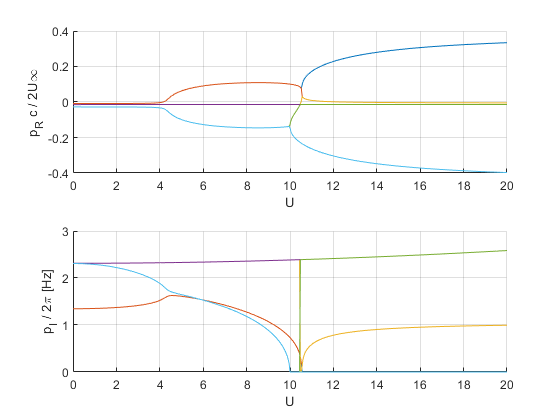


% Plotting
figure
for j = 1:6
    subplot(2,1,1)
    hold on
    plot(U_,real(p_(j,:).*cnum./(2*U_)));
    xlabel('U')
    ylabel('p_R c / 2U\infty')
    grid on
    subplot(2,1,2)
    hold on
    plot(U_,abs(imag(p_(j,:))/(2*pi)));
    xlabel('U')
    ylabel('p_I / 2\pi [Hz]')
    grid on
end

*k-method*

% k-method
% Defining the Theodorsen's function:
C = @(k) 1 - 0.165/(1-1i*0.045/k) - 0.335/(1-1i*0.3/k);

% Inverse k vector (k^-1 = (2*Uinf)/(omega*c))
invk_ = linspace(0.001,5,500);
l_ = zeros(3,length(invk_));
Vk_ = zeros(3,3,length(invk_));

% Sweep through inverse of k
for i = 1:length(invk_)
    
    % Get reduced frequency
    k = 1/invk_(i);
    
    % Compute effective mass expression
    Meffnum = Mnum + pi*rhoinfnum*cnum^3/(4*k^2)*(C(k)*A0num - 1i*k*(C(k)*A1cnum - A1ncnum));
    
    % Solve the eigenvalues problem
    [Vk,Dk] = eig(Meffnum,Knum); % We use the opposite (usually it is eigs(K,M) but now it the opposite: see equations of page T2.2-8 --> we have the eigenvalue (lambda) multiplying the K matrix instead of the Meff matrix)
   
    % Sort (the following algorithm analyses the previous iteration and saves the colsest one to the actual iteration, and we will elimiate this value)
    if i > 1
        % it could be added to the p-method to elimiate the jupms
        l = diag(Dk);
        tosort = 1:3;
        for j = 1:3
            [~,jmin] = min(abs(real(l(tosort))-real(l_(j,i-1))) + abs(imag(l(tosort))-imag(l_(j,i-1)))); % to find from all the previous eigenvalues which is the closest one (difference between the real part and the imaginary part)
            l_(j,i) = l(tosort(jmin));
            Vk_(:,j,i) = Vk(:,tosort(jmin));
            tosort(jmin) = [];
        end
    else
        l_(:,1) = diag(Dk);
    end
end
wk_ = sqrt(1./real(l_));
gk_ = imag(l_)./real(l_);
Uk_ = wk_*cnum.*invk_/2;


% Finding flutter speed for k
Ufk = 0;
i = 1;
while Ufk == 0
    for j = 1:length(gk_(:,i))
        if real(gk_(j,i))>0
            Ufk = Uk_(i);
        end
    end
    i = i + 1;
end
disp(["The flutter speed for the k method is: ", num2str(Ufk), "m/s"])

    "The flutter speed for the k method is: "    "2.3775"    "m/s"



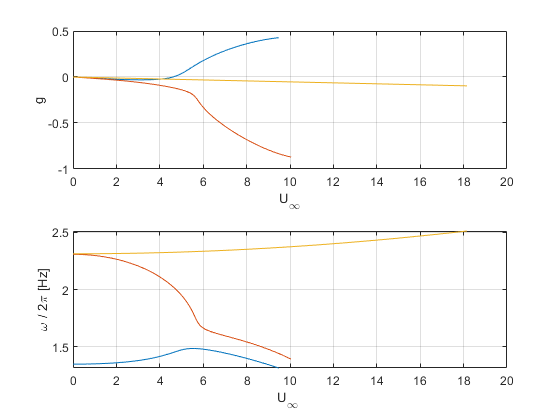


figure
subplot(2,1,1)
plot(Uk_',gk_');
xlabel("U_\infty");
ylabel("g");
xlim([0 20])
grid on
subplot(2,1,2)
plot(Uk_',wk_'/(2*pi));
xlabel("U_\infty ");
ylabel("\omega / 2\pi [Hz]");
xlim([0 20])
grid on

*p-k method*

% Numerical variables
tol = 1e-6; 
max_iter = 100;

% Variables
gam_ = zeros(3, length(U_));
w_ = zeros(3, length(U_));
Vpk_= zeros(3, length(U_));

% First guess for frequencies
[~,Ds] = eig(Knum,Mnum);
w_(:,1) = sqrt(diag(Ds));

% Loop through velocites
for i = 1:length(U_)

    if i>1
        w_(:,i) = w_(:,i-1);
        gam_(:,i) = gam_(:,i-1);
    end
    
    for j = 1:3
        conv = 1;
        iter = 0;
        
        while conv > tol && iter < max_iter
            iter = iter+1;
            
            % Get reduced frequency
            k = w_(j,i)*cnum/(2*U_(i));
            
            % Compute effective matrices
            Keff = Knum - pi*rhoinfnum*U_(i)^2*cnum*(C(k)*A0num - 1i*k*(C(k)*A1cnum-A1ncnum));
            
            % Extend system matrices
            Anum = [Keff, zeros(3,3); zeros(3,3), eye(3,3)];
            Bnum = [zeros(3), -Mnum; eye(3,3), zeros(3,3)];

            % Solve eigenvalues
            [Vpk, Dpk] = eig(Anum,Bnum);
            p = diag(Dpk);
            
            % Look for closest node to initial guess (w_ and gam_)
            [conv,jmin] = min(abs(real(p)-gam_(j,i)) + abs(imag(p)-w_(j,i)));
            
            % Store the newer values as initial guesses or previous values
            w_(j,i) = imag(p(jmin));
            gam_(j,i) = real(p(jmin));
            Vpk_(:,j,i) = Vpk(1:3,jmin);
            
            
        
        end
        
    end
    
end

% Finding flutter speed for pk
Ufpk = 0;
i = 1;
while Ufpk == 0
    for j = 1:length(gam_(:,i))
        if gam_(j,i)>0
            Ufpk = U_(i);
        end
    end
    i = i + 1;
end
disp(["The flutter speed for the pk method is: ", num2str(Ufpk), "m/s"])

    "The flutter speed for the pk method is: "    "4.6408"    "m/s"



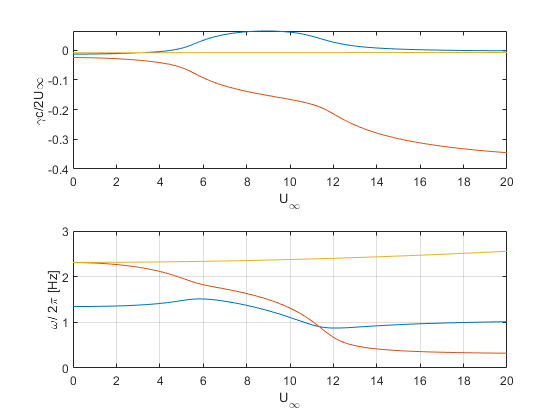


figure
subplot(2,1,1)
plot(U_, gam_.*cnum./(2*U_))
xlabel("U_\infty")
ylabel("\gammac/2U\infty")
subplot(2,1,2)
plot(U_, w_/(2*pi))
xlabel("U_\infty")
ylabel("\omega/ 2\pi [Hz]")
grid on